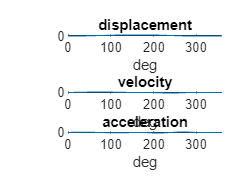

figure(1)
tiledlayout(3,1)
syms deg(t);
omega=1000*2*pi/60;

nexttile
poly=0.025*(10*(deg).^3/150.^3-15*(deg).^4/150.^4+6*(deg).^5/150.^5);
dwell1=0.025;
cycloid=-0.025*((deg-180)/120-sin(2*pi*(deg-180)/120)/(2*pi))+0.025;
dwell2=0.00;
y=piecewise(deg<150, poly, 150<deg<180, dwell1, 180<deg<300, cycloid, 300<deg<360,dwell2);
y=subs(y,deg,t);
fplot(y);
xlim([0 360]);
title("displacement")
ylabel("m")
xlabel("deg")

nexttile
vdwell1=0;
vcycloid=subs(diff(cycloid),diff(deg),omega);
vdwell2=0;
vpoly=subs(diff(poly),diff(deg),omega);
v=piecewise(deg<150, vpoly, 150<deg<180, vdwell1, 180<deg<300, vcycloid, 300<deg<360,vdwell2);
v=subs(v,diff(deg),omega);
v=subs(v,deg,t);
fplot(v);
xlim([0 360])
title("velocity")
ylabel("m/s")
xlabel("deg")

nexttile
adwell1=0;
acycloid=subs(diff(vcycloid),diff(deg),omega);
adwell2=0;
apoly=subs(diff(vpoly),diff(deg),omega);
a=piecewise(deg<150, apoly, 150<deg<180, adwell1, 180<deg<300, acycloid, 300<deg<360,adwell2);
a=subs(a,diff(deg),omega);
a=subs(a,deg,t);
fplot(a);
xlim([0 360])
title("acceleration")
ylabel("m/s^2")
xlabel("deg")

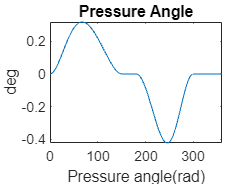


%b
figure(2)
phi=atand((v/omega)/(0.045+y));
fplot(phi);
xlim([0 360]);
title("Pressure Angle")
xlabel("Pressure angle(rad)")
ylabel("deg")

%c
figure(3)
nexttile

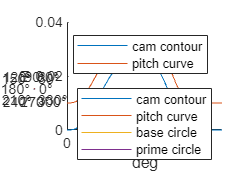

hold on
fplot(y);
fplot(y+0.010);
xlabel("deg");
ylabel("m")
legend("cam contour","pitch curve");
xlim([0 360]);

figure(4)
ax=polaraxes;
theta=0:0.1:360;
thetarad=deg2rad(theta);
polarplot(thetarad,y(theta)+0.035);
hold on
polarplot(thetarad,y(theta)+0.045);
polarplot(thetarad,0.035+zeros(size(thetarad)));
polarplot(thetarad,0.045+zeros(size(thetarad)));
legend("cam contour","pitch curve","base circle","prime circle");

ax.ThetaZeroLocation='top';
hold off